# FFT Analysis 

Review how to apply FFT of signals

After this tutorial, do DTA_FreqFeatureExercise.mlx

## Dataset

### Generate Signals

A signal with a sampling frequency of 1 kHz and a signal duration of 1 second.

Form a signal containing a 50 Hz sinusoid and 120Hz sinusoid 

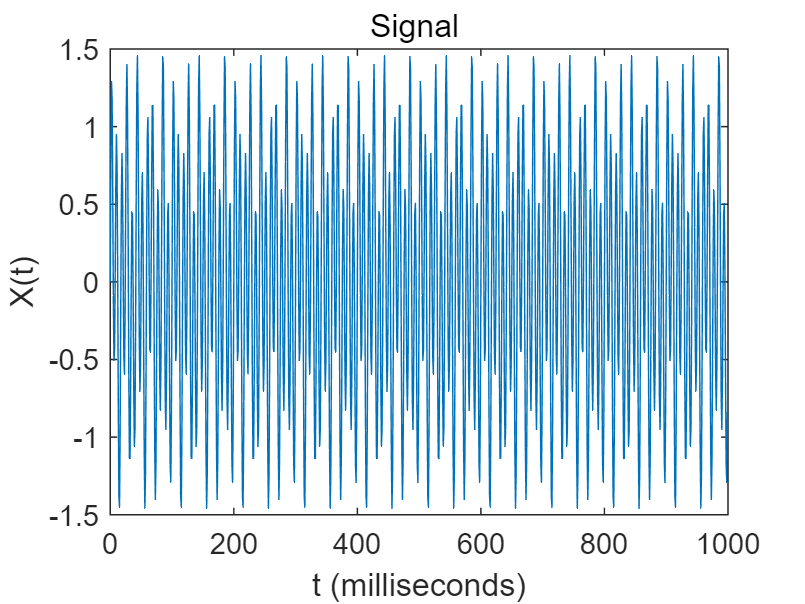

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 1000;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
fa=50;      % 10Hz signal
fa2=120;    % 55Hz signal
X = 0.0 + 0.5* sin(2.0*pi*fa*t)+1*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

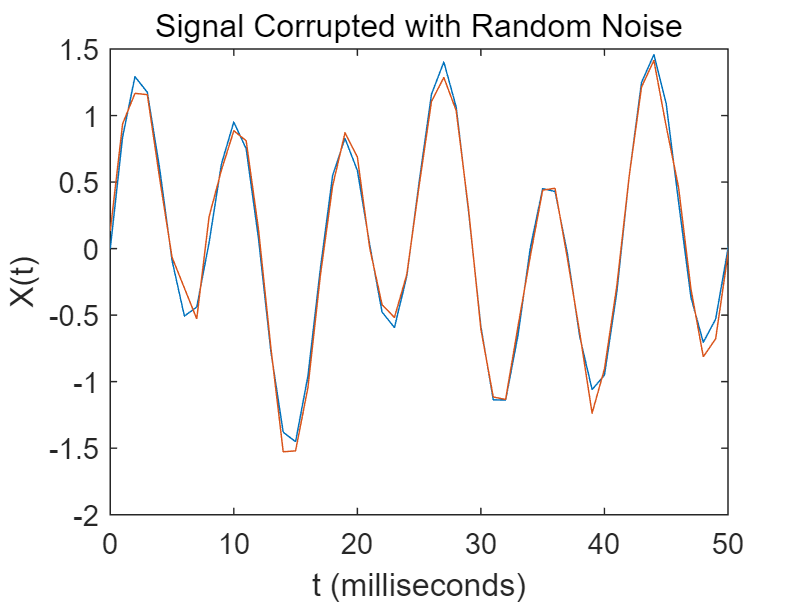



% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xm = X+noise; 


% Plot signals
figure(1)
plot(1000*t,X, 1000*t,Xm)
title('Signal Corrupted with Random Noise')
xlabel('t (milliseconds)')
ylabel('X(t)')
xlim([0 50])

# FFT Analysis

- Fourier Transform of the Signal 

-  Inverse Fourier Transform to get time domain signal

-  Power specturm  of the signal

### Exercise1: Fourier Transform of the Signal

Assume the signal is real-valued and has even length. 

Then, power estimates for the positive  frequencies will be used. Zero frequency (DC) and the Nyquist frequency do not occur twice. 

%%% Input for FFT
x=X;    %x=Xm;
L=length(x);


%%% Apply FFT of x
% YOUR CODE GOES HERE
% Y=fft(    )   


%%% Compute the two-sided spectrum P2
% Then compute the single-sided spectrum P1 based on P2 and the even-valued signal length L.
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
% YOUR CODE GOES HERE
% P1(    )=  


%%% Define the frequency domain f (x-axis)
% YOUR CODE GOES HERE
% f =  

Plot single-sided spectrum P

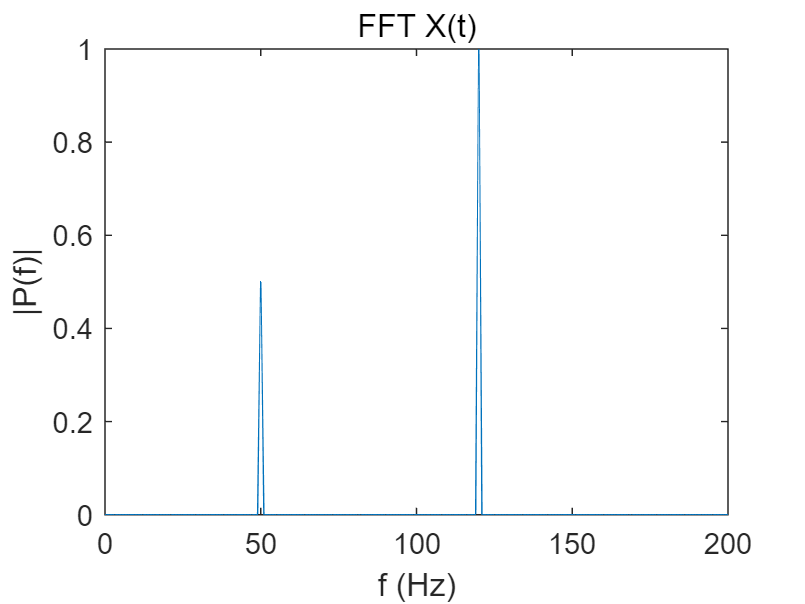


figure
plot(f,P1) 
title('FFT X(t)')
xlabel('f (Hz)')
ylabel('|P(f)|')
xlim([0 200])

### Exercise 2: 

Create a module that returns single-sided FFT 

% YOUR CODE GOES HERE
p1=getFFT(X,L);  % CREATE function


figure
plot(f,p1) 
title('FFT X(t)')
xlabel('f (Hz)')
ylabel('|P(f)|')
xlim([0 200])

### Exercise3: Inverse Fast Fourier Transform 

%%% Apply iFFT of x
% Given  Y = fft(x,L);

% YOUR CODE GOES HERE
% xi = ____________;

% Plot signals
figure()
plot(1000*t,x,'-', 1000*t,xi,'.')
title('IFFT')
xlabel('t (milliseconds)')
ylabel('X(t)')
xlim([0 50])

### Exercise 4: PSD(power spectrum density)

Assume the signal is real-valued and has even length. 

Then, power estimates for the positive  frequencies will be used, as we did in single-sided spectrum. 

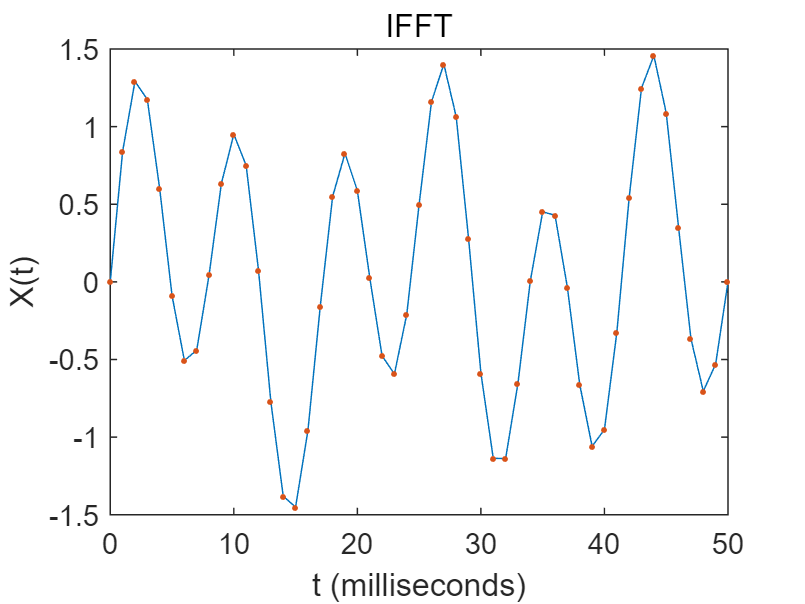

Y = fft(x,L);

P2 = abs(Y);    % Not normalized by L as fft
psdx = (1/(Fs*L))*P2(1:L/2+1).^2;  % Power normalized by L and Fs
psdx(2:end-1) = 2*psdx(2:end-1);
f = 0:Fs/L:Fs/2;

figure
plot(f,10*log10(psdx))
grid on
title('Periodogram Using FFT')
xlabel('Frequency (Hz)')
ylabel('Power/Frequency (dB/Hz)')
% CREATE YOUR FUNCTION
% YOUR CODE GOES HERE
psdx2=getPSD(x,L,Fs)


## Further Reading

### Power Spectrum: pspectrum()

- If possible, the function computes a single modified periodogram of the whole signal using a Kaiser window.

- If it is not possible to compute a single modified periodogram in a reasonable amount of time, the function computes a Welch periodogram: It divides the signal into overlapping segments, windows each segment using a Kaiser window, and averages the periodograms of the segments.

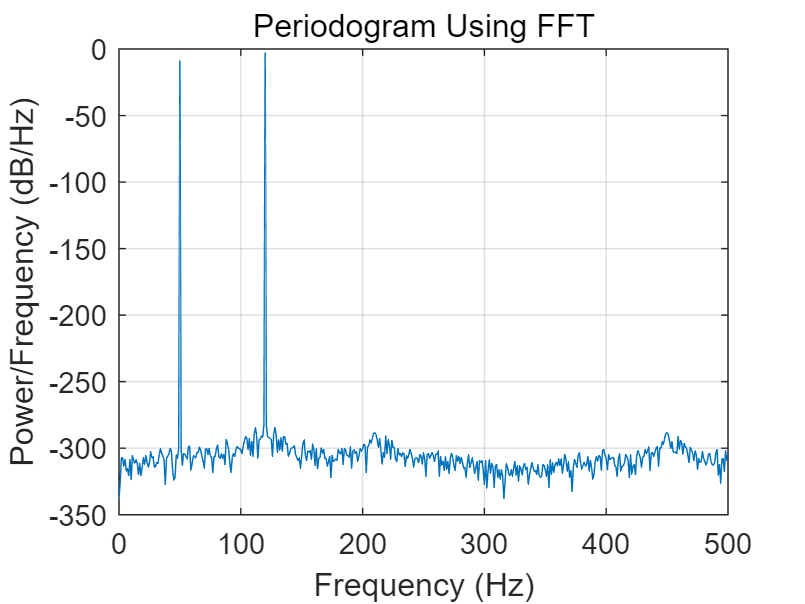

[pxx,fp] = pspectrum(x,Fs,'FrequencyResolution');


plot(fp,pow2db(pxx))
grid on
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')
title('pspectrum')

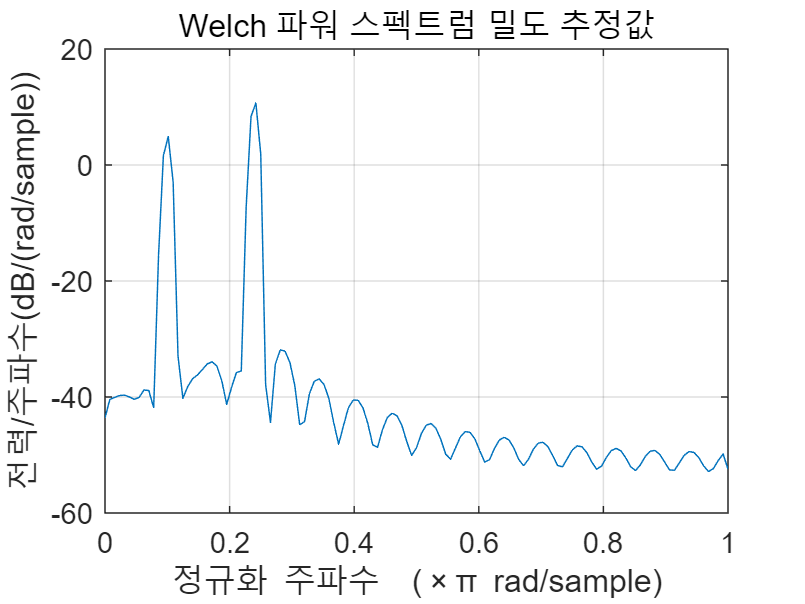

% Also read about  for Welch’s power spectral density estimate
pxx = pwelch(x);

pwelch(x)
